# Effect of Pole Locations: 2nd Order Poles

First let's define the Laplace variable s, which we can use to build transfer functions

s = tf('s');

## Define the pole

Let's define the real part and imaginary part of the pole.

sigma = -2.9;  % real part
omega = 5.1;  % imag part 

Try different values of $\sigma
$ and $\omega$ to see how the system responds.

If the imaginary part is non-zero, then the pole is complex.  For real systems with real coefficients in their differential equations, complex poles always come in *complex conjugate pairs.  *


$$p = \sigma \pm j \omega$$


p1 = sigma + 1i*omega;  % one value of the pole
p2 = sigma - 1i*omega;  % the complex conjugate of p1

## Create the transfer function with the pole

We will assume the tranfer function is


$$G(s) = \frac{1}{2} \left( \frac{1}{s - p_1} + \frac{1}{s - p_2} \right) = \frac{ s + \sigma}{s^2 + 2 \sigma s + \omega_n^2$$


G = 0.5*(1/(s - p1) + 1/(s - p2))

G =
 
        s + 2.9
  -------------------
  s^2 + 5.8 s + 34.42
 
Continuous-time transfer function.



## Show where the poles are on the s-plane

A pole zero map shows the locations of all of the zeros and all of the poles of a transfer function.  With this we have a picture of whether the poles are in the LHP or RHP.

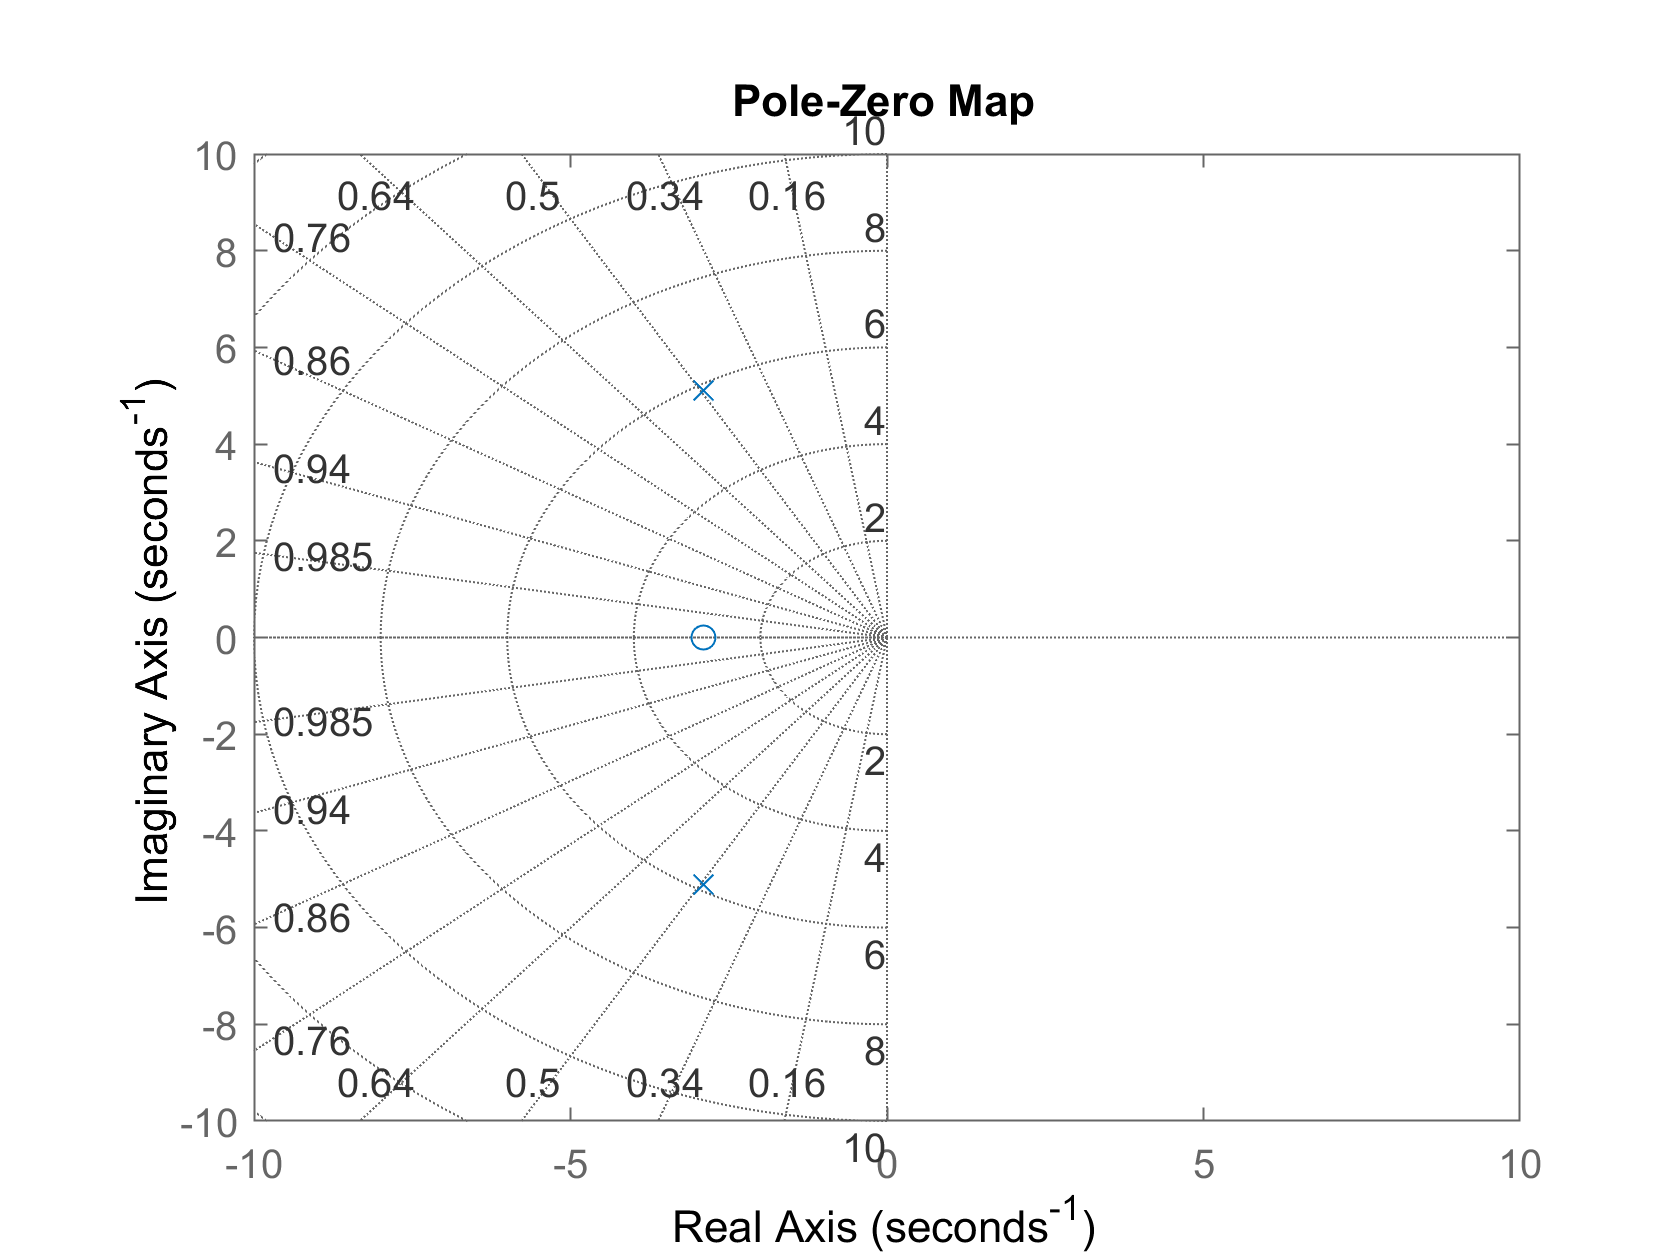

pzmap(G),axis([-10 10 -10 10])
grid on

## Look at the impulse response to the effect of pole location

Now lets look at an impulse response of the system.

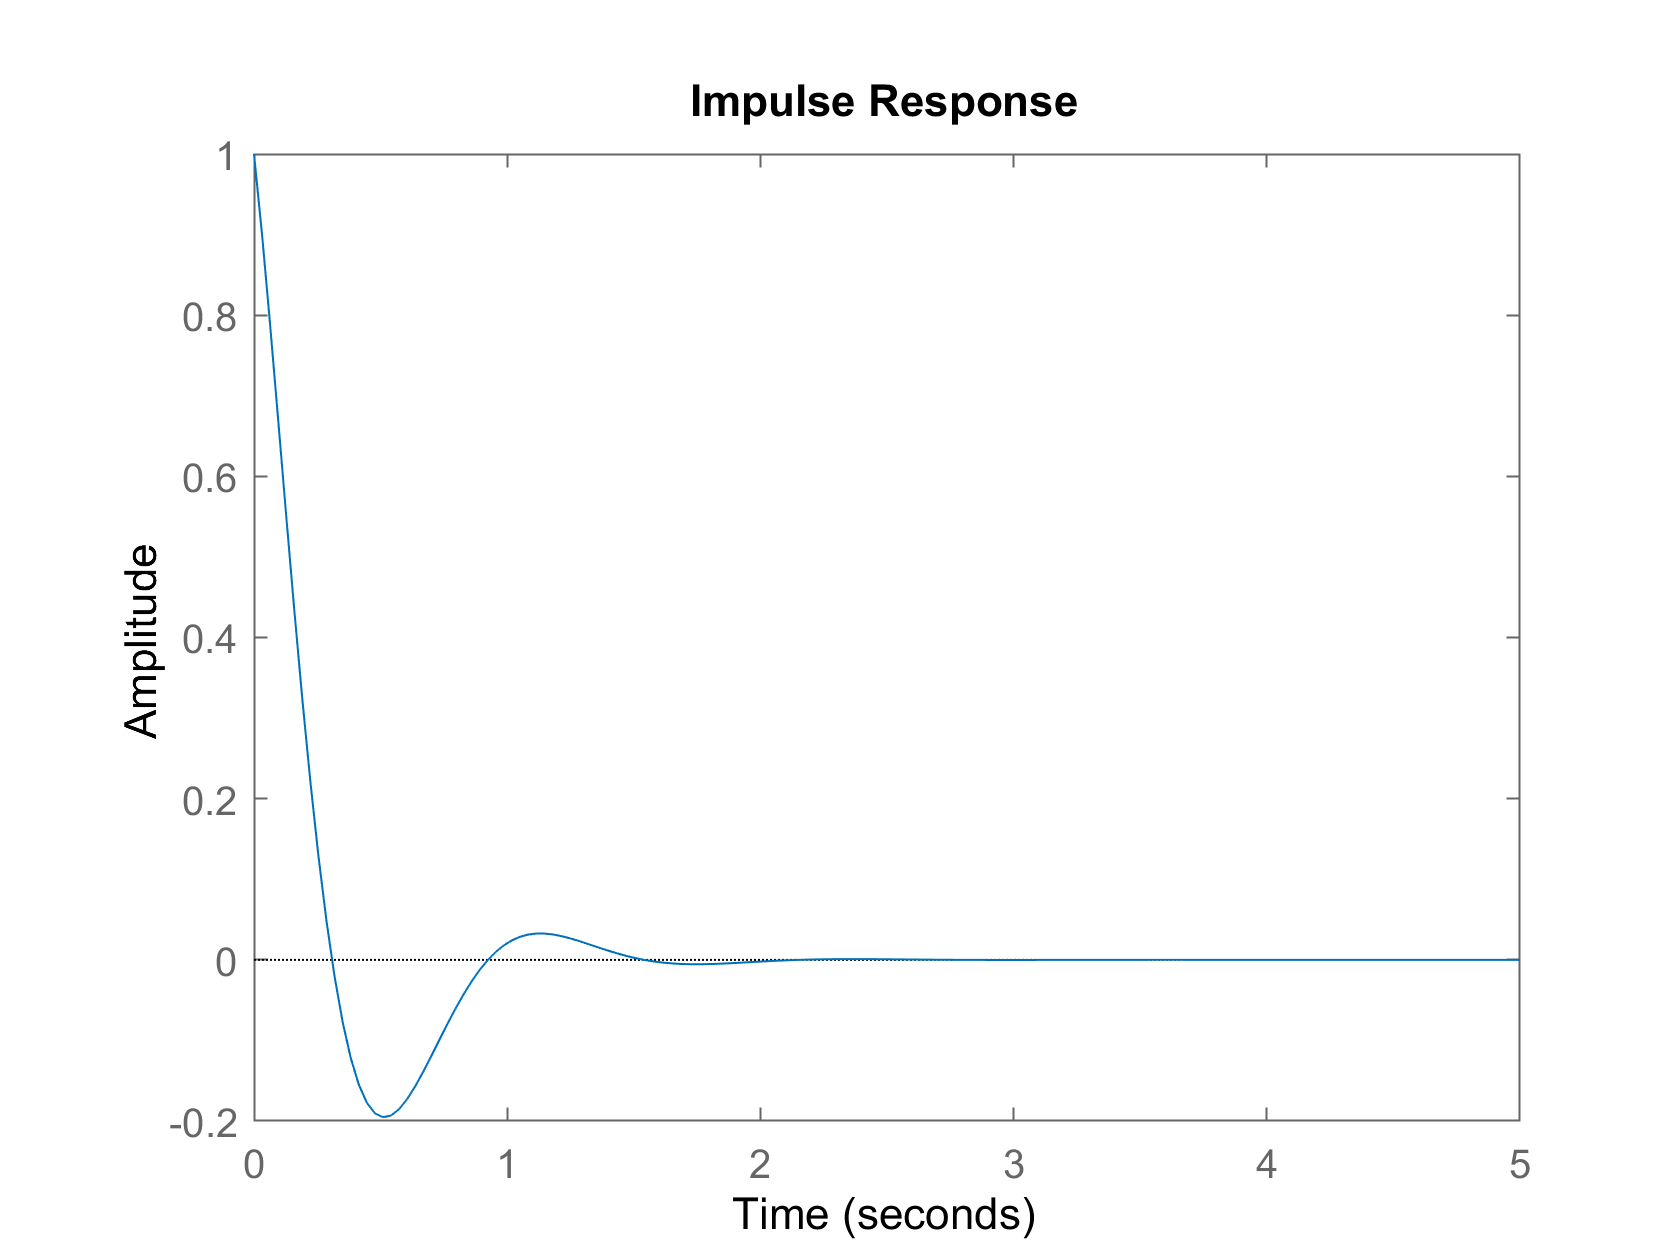

Tfinal = 5;     % the final time of the response
impulse(G,Tfinal);

One good thing about our choice for $G(s)$ is that we know its inverse Laplace transform.  This means we know the system's impulse response function


$$g(t) = {\cal L}^{-1}\{ G(s) \} = e^{\sigma t}\cos \omega t$$


This oscillates like $\cos \omega t$ and decays like $e^{\sigma t}$.  Let's plot these with the impulse response

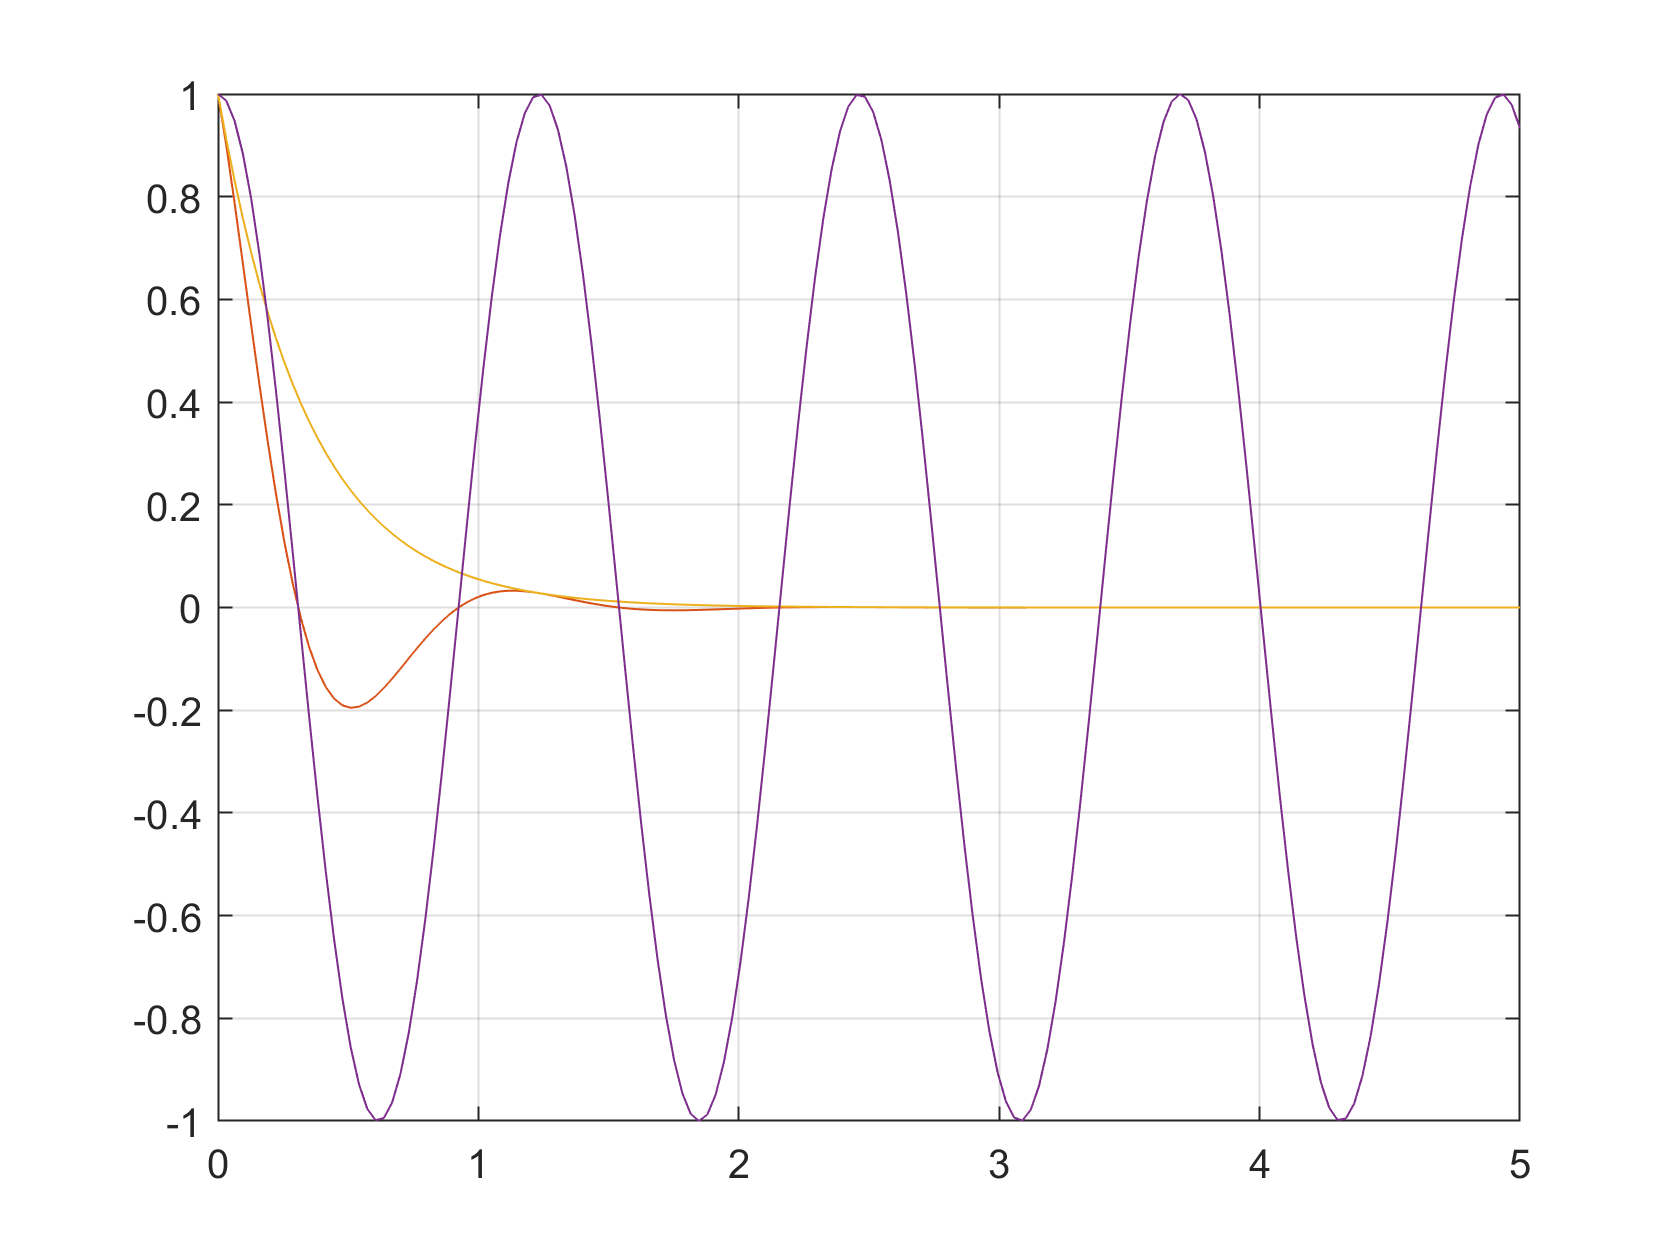

[output,t] = impulse(G,Tfinal);
g = exp(sigma*t).*cos(omega*t);
plot(t,output,...
    t,g,...
    t,exp(sigma*t),...
    t,cos(omega*t))
grid on

## Look at the step response

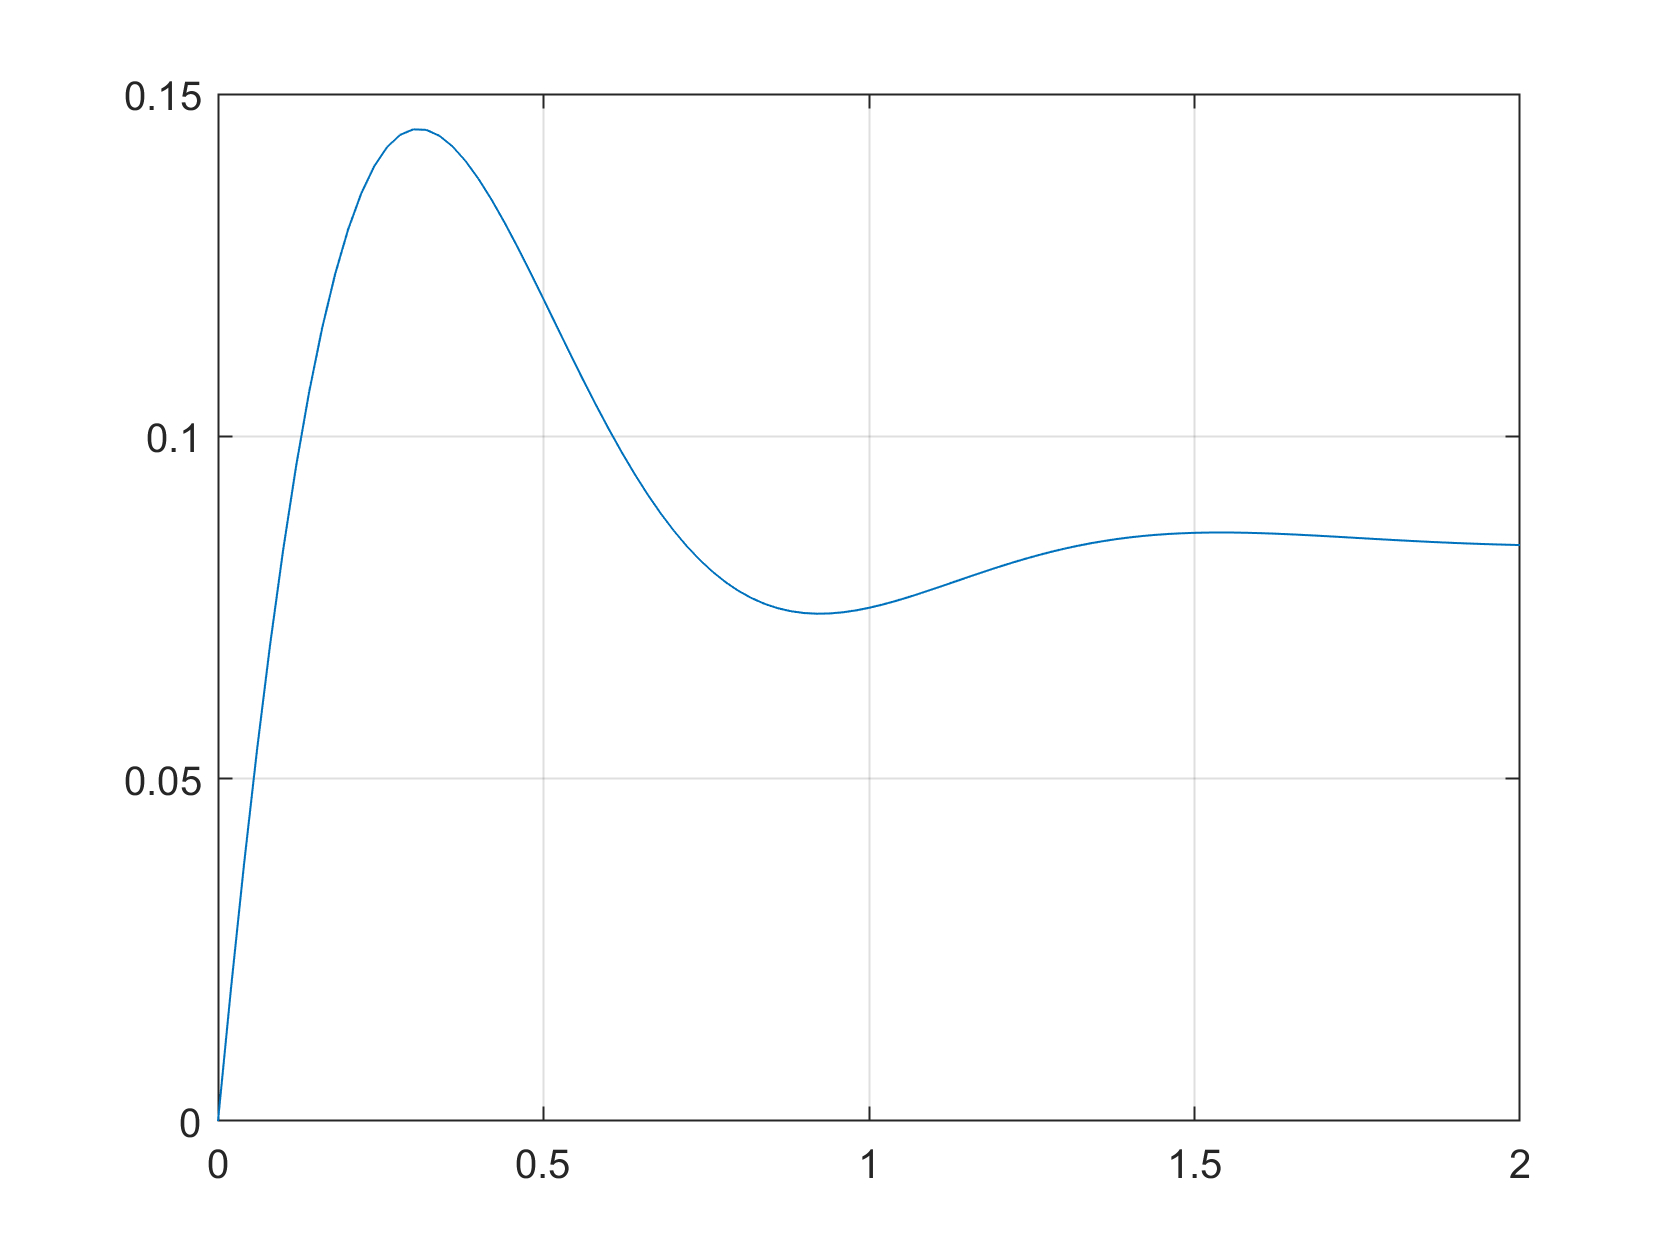

Tfinal = 2;     % the final time of the response
[output,t] = step(G,Tfinal);
plot(t,output)
grid on